states = geoshape(shaperead('usastatehi', 'UseGeoCoords', true));
stateName = 'Oklahoma';
oceanColor = [.5 .7 .9];
OK = states(strcmp(states.Name, stateName));
route = gpxread('E:\MATLAB Drive\Eclipse\Zac Acer\6.12.2020\groundtrack2020061218Z_H2514394.gpx');

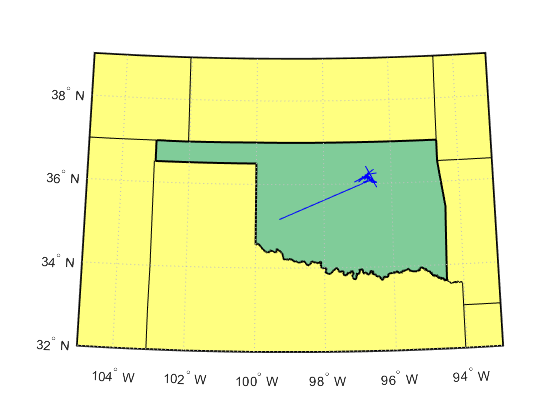

figure (2)
clf
ax = usamap('ok');
setm(ax, 'FFaceColor', oceanColor)
geoshow(states)
geoshow(OK, 'LineWidth', 1.5, 'FaceColor', [.5 .8 .6])
geoshow(route.Latitude, route.Longitude);

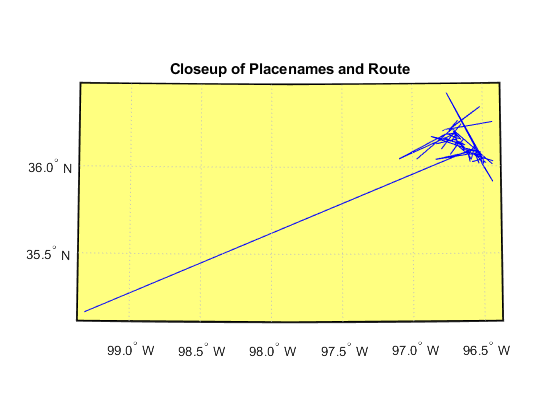


z = 44;
a = route.Latitude(1:(end-z));
lat = [route.Latitude ];
lon = [route.Longitude ];
latlim = [min(lat) max(lat)];
lonlim = [min(lon) max(lon)];
[latlim, lonlim] = bufgeoquad(latlim, lonlim, .05, .05);

figure
ax = usamap(latlim, lonlim);
setm(ax, 'FFaceColor', oceanColor)
geoshow(states)
geoshow(route.Latitude, route.Longitude)
title('Closeup of Placenames and Route')